mapData = load("occupancy_map_3d.mat", "omap3D")

mapData = struct with fields:
    omap3D: [1×1 occupancyMap3D]


omap = mapData.omap3D

omap =   occupancyMap3D with properties:

    ProbabilitySaturation: [1.0000e-03 0.9990]
               Resolution: 1
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000


omap.FreeThreshold = omap.OccupiedThreshold;

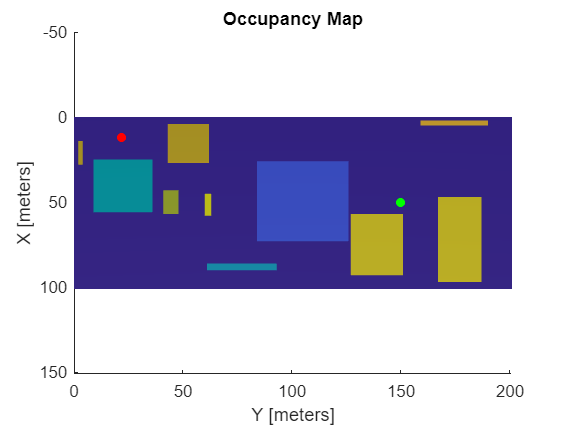

startPose = [12 22 25 pi/2];
goalPose = [50 150 35 pi/2];
figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
hold off
view([90 90])

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/6,...
                                "AirSpeed",6,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[-20 220; -20 220; 10 100; -pi pi]);

'ExampleHelperUAVStateSpace' is used in Motion Planning with RRT for Fixed-Wing UAV .

threshold = [(goalPose-0.5)' (goalPose+0.5)'; -pi pi];
sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.1;

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 50;
planner.GoalBias = 0.10;  
planner.MaxIterations = 400;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 5);

[pthObj,solnInfo] = plan(planner,startPose,goalPose);